# [RLRPSB] Reinforcement Learning on Resistive Piezoelectric Shunt with a Beam with Matlab RLC

Author: Febvre Maryne

Date: 04/2022 

Objective: This script observes the dynamic behavior of a cantilever beam using a finite element model (FEM). The beam has piezoelectric patches for sensing and actuation. Shunt control is applied on the piezoelectric transducers using, Resistive shunts. Optimal shunt tuning is performed using Deep Reinforcement Learing strategy.

clc 
clf
close all
clear all

Load model data computed from script : 'Smart_cantilever_beam_1D_FEM_livescript.mlx'

load('Datas/FEM_smart_beam.mat','Sys_sc','Sys_oc','Sys_rs')

Flag to save figures (set to 1 to save)

save_figure_var = 0; % 1 to save figure, 0 to not save

Flag to train the algorithm (set true to train)

doTraining = true%false; %true to train otherwise it load data

doTraining = logical
   1


Chose the algorithm to train (PPOO or TRPO)

algo = 'PPOO' %'TRPO'%

algo = 'PPOO'

## Shunt control implementation

This section exposes the implementation of variours shunt control applied on the finite element smart structure. Examples are given with Resistive (R), Resistive Inductuve (RL) and Resistive Capacitive (RC) series shunts.

### Setup parameters for the feedback control

Define laplace variable:

s = tf('s');

Define system control inputs and outputs

feedin = 1;  % Moment applied (input)
feedout = 1;  % Output is the charge q

#### Bode response

Create a figure for plotting the frequency response results

interval_plot = [2000:0.01:4500];  % Frequency interval for Bode plot

Input disturbance of the transfert function 

input_tf = 2; % Input Force Fu, Chose input_tf = 1; for Input q. 

Output measurement of the transfert function 

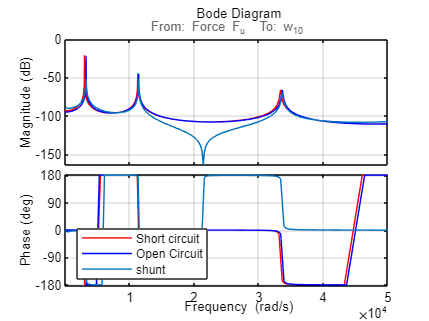

ouput_tf = 20 ; % Output measurement w_10 displacement at the free beam end. 

bopt=bodeoptions;
bopt.FreqScale='Linear';
bopt.PhaseWrapping ='on';
bopt.Grid='on';
bopt.XLim={[1 5e4]};
fig1=figure;

fig1.Name='Bode plot';
hold on
bodeplot(Sys_sc(ouput_tf, input_tf),'r',bopt)
bodeplot(Sys_oc(ouput_tf, input_tf),'b',bopt)
Controle=s*1e7;
Sys_rs_contr_R = feedback(Sys_rs,Controle, feedin, feedout);
bode(Sys_rs_contr_R(ouput_tf, input_tf),bopt)
legend('Short circuit', 'Open Circuit','shunt','Location','southwest')
hold off

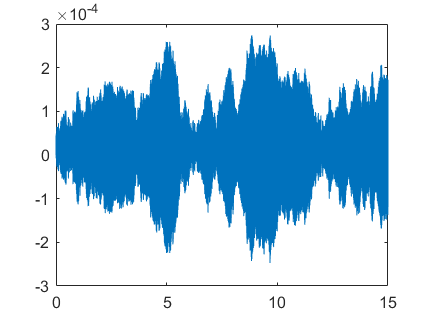

Tf = 15.0;
Ts = 1.0e-5;
time=0:Ts:Tf;
Sys_rs_contr_0 = feedback(Sys_rs,0,feedin, feedout);
noise = rand(length(time),1);
w10_wn=lsim(Sys_rs_contr_0(ouput_tf, input_tf),noise,time);

figure
plot(time,w10_wn)

## Step 2: Reinforcement Learning 

Specify the simulation time `Tf` and the agent sample time `Ts` in seconds.

Tf = 1;
Ts = 1.0e-5;
%Ts = 9.6e-7;

### *Step 2-1: Define Environment:*

Action and observation signals that the agent uses to interact with the environment.

#### *Observation*

- An `rlFiniteSetSpec` object specifies discrete action or observation data specifications for reinforcement learning environments.

- An `rlNumericSpec` object specifies continuous action or observation data specifications for reinforcement learning environments.

numObs = 2;
length([0:Ts:Tf])

ans = 100001


obsInfo=rlNumericSpec([numObs 1], ...
    'LowerLimit',-inf ,...
    'UpperLimit',inf)

obsInfo =   rlNumericSpec with properties:

     LowerLimit: -Inf
     UpperLimit: Inf
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [2 1]
       DataType: "double"


obsInfo.Name='observation';
obsInfo.Description='q, w10';

#### *Action*

numAct = 1%3

numAct = 1

% actInfo = rlNumericSpec([numAct 1], ...
%     'LowerLimit',[1; -15; 1],...
%     'UpperLimit',[10; -5; 10])
actInfo = rlNumericSpec([numAct 1], ...
    'LowerLimit',[1],...
    'UpperLimit',[7])

actInfo =   rlNumericSpec with properties:

     LowerLimit: 1
     UpperLimit: 7
           Name: [0×0 string]
    Description: [0×0 string]
      Dimension: [1 1]
       DataType: "double"


actInfo.Name = 'Contole R';

#### *Environment*

Build the environment interface object.

G=Sys_rs(1,1);
env2=Env_Passive_crtl_freq_time(Sys_rs,Ts,Tf,obsInfo,actInfo,noise,time);

init


Set a custom reset function that randomizes the reference values for the model.

%env.ResetFcn = @(in)localResetFcn(in);

Fix the random generator seed for reproducibility.

rng(0)

### *Step 2-2: Define Agent:*

### *Agent*

*Defaults parameters*

nNN=5

nNN = 5

criticNet = localCreateCriticNetwork(obsInfo,actInfo,nNN)

criticNet =   LayerGraph with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
    Connections: [5×2 table]
     InputNames: {'input_1'}
    OutputNames: {1×0 cell}


Critic = rlValueFunction(criticNet,obsInfo);

actorNet = localCreateActorNetwork(obsInfo,actInfo,nNN)

actorNet =   LayerGraph with properties:

         Layers: [10×1 nnet.cnn.layer.Layer]
    Connections: [9×2 table]
     InputNames: {'input_1'}
    OutputNames: {1×0 cell}


Actor = rlContinuousGaussianActor(actorNet, obsInfo, actInfo, ...
            'ActionMeanOutputNames','scale',...
            'ActionStandardDeviationOutputNames','std',...
            'ObservationInputNames','input_1');

% figure
% plot(Critic)

if algo =='TRPO'
    agent = rlTRPOAgent(Actor, Critic)
else 
    agent = rlPPOAgent(Actor, Critic)
end

agent =   rlPPOAgent with properties:

            AgentOptions: [1×1 rl.option.rlPPOAgentOptions]
    UseExplorationPolicy: 1
         ObservationInfo: [1×1 rl.util.rlNumericSpec]
              ActionInfo: [1×1 rl.util.rlNumericSpec]
              SampleTime: 1


## Step 3 - Training

### *Step 3-1: Training options:*

**Training Setup**

Configure the training to use the following options:

- Set up the training to last at most 5000 episodes, with each episode lasting at most 250 steps.

- To calculate the discounted reward, choose a discount factor of 0.995.

- Terminate the training after the maximum number of episodes is reached or when  the average reward across 100 episodes reaches the value of 220.

Create a vector for storing the cumulative reward for each training episode.

obs=reset(env2)

obs =     0.0002
    0.0846


% Import piezoelectric transducer properties
load('Datas/FEM_smart_beam.mat','l_piezo','L_piezo','h_piezo','epsilon_33_S','d13','E_piezo_13')

% Get the poles and zeros for short circuit case
poles_sc = pole(Sys_sc(ouput_tf, input_tf));
poles_oc = pole(Sys_oc(ouput_tf, input_tf));

% Calculate the natural frequency of short circuit in Hz
omega0_sc_pole = abs(min(poles_sc)) / (2 * pi()); 
omega0_oc_pole = abs(min(poles_oc)) / (2 * pi()); 
Cpi = l_piezo * L_piezo * epsilon_33_S / h_piezo;
k31_hagood=sqrt((omega0_oc_pole^2-omega0_sc_pole^2)/omega0_sc_pole^2)

k31_hagood = 0.4161

% Optimal parameters from transfer function consideration
delta_opt_TF = sqrt(1 + k31_hagood^2);
r_opt_TF = sqrt(2) * k31_hagood / (1 + k31_hagood^2);

% Calculate the optimal resistance in transfer function form
R_opt_Hagood = r_opt_TF / (Cpi * omega0_sc_pole);

action = {[log10(R_opt_Hagood)]};
[nextObs,reward,isdone] = step(env2,action{1})

Action = 4.8293

distReward = 11.3358

nextObs =     0.0002
    0.0846


reward = 11.3358

isdone = logical
   1


stop_training_value=round(reward,4)

stop_training_value = 11.3358

env=env2;

simOpts = rlSimulationOptions('MaxSteps',1,'NumSimulations',1,'StopOnError','on');

trainOpts = rlTrainingOptions(...
    'MaxEpisodes',1000,...
    'MaxStepsPerEpisode',10,...
    'Plots','training-progress',...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',stop_training_value,...
    'ScoreAveragingWindowLength',10,...
    'SaveAgentCriteria',"AverageReward", ...
    'SaveAgentValue',400);

### *Step 3-2: Training:*

*GPU parameter*

if canUseGPU
    executionEnvironment = "gpu";
    numberOfGPUs = gpuDeviceCount;
    "can use GPU"
else
    executionEnvironment = "cpu";
    pool = parpool;
end

ans = "can use GPU"

**Custom Training Loop**

The algorithm for the custom training loop is as follows. For each episode:

- Reset the environment.

- Create buffers for storing experience information: observations, actions, and rewards.

- Generate experiences until a terminal condition occurs. To do so, evaluate the  policy to get actions, apply those actions to the environment, and  obtain the resulting observations and rewards. Store the actions,  observations, and rewards in buffers.

- Collect the training data as a batch of experiences.

- Compute the episode Monte Carlo return, which is the discounted future reward.

- Compute the gradient of the loss function with respect to the policy parameters.

- Update the policy using the computed gradients.

- Update the training visualization.

- Terminate training if the policy is sufficiently trained.

if doTraining
    % Train the agent.
    warning('off','all')
    trainingStats = train(agent,env,trainOpts)
else
    % Load the pretrained agent for the example.
    if algo=='TRPO'
        mdl="Datas\Model_EF_Tune_Shunt_R_TRPO.mat";
    else 
        mdl="Datas\Model_EF_Tune_Shunt_R_PPO.mat";
    end
    load(mdl,'agent','trainingStats')
    plot(trainingStats)
end

Action = 4.4066

distReward = 9.4442

Action = 3.2971

distReward = 2.4579

Action = 5.7979

distReward = 12.8211

Action = 2.8797

distReward = 0.5359

Action = 3.6251

distReward = 4.5377

Action = 3.8470

distReward = 6.0399

Action = 4.1157

distReward = 7.7754

Action = 3.4383

distReward = 3.3110

Action = 2.7231

distReward = 0.0614

Action = 4.6418

distReward = 10.5894

Action = 3.9810

distReward = 6.9246

Action = 2.8370

distReward = 0.3940

Action = 4.6846

distReward = 10.7742

Action = 5.1374

distReward = 12.1959

Action = 4.2281

distReward = 8.4492

Action = 3.7781

distReward = 5.5757

Action = 5.1190

distReward = 12.1569

Action = 3.9577

distReward = 6.7735

Action = 5.4330

distReward = 12.6390

Action = 3.9889

distReward = 6.9754

Action = 4.7802

distReward = 11.1566

Action = 5.1552

distReward = 12.2322

Action = 4.8758

distReward = 11.4951

Action = 4.8019

distReward = 11.2371

Action = 5.0047

distReward = 11.8810

Action = 5.4114

distReward = 12.6170

Action = 4.6913

distReward = 10.8020

Action = 4.7672

distReward = 11.1069

Action = 5.0730

distReward = 12.0532

Action = 4.0684

distReward = 7.4820

Action = 5.1315

distReward = 12.1836

Action = 4.7125

distReward = 10.8899

Action = 4.5012

distReward = 9.9295

Action = 4.6532

distReward = 10.6396

Action = 5.9179

distReward = 12.8151

Action = 4.5784

distReward = 10.3014

Action = 5.2138

distReward = 12.3421

Action = 4.4360

distReward = 9.5983

Action = 2.8909

distReward = 0.5746

Action = 5.7199

distReward = 12.8090

Action = 4.1467

distReward = 7.9650

Action = 5.3310

distReward = 12.5218

Action = 5.6731

distReward = 12.7953

Action = 4.0219

distReward = 7.1874

Action = 4.5217

distReward = 10.0304

Action = 4.6010

distReward = 10.4061

Action = 5.6707

distReward = 12.7944

Action = 6.3027

distReward = 12.6103

Action = 4.9180

distReward = 11.6305

Action = 6.3005

distReward = 12.6123

Action = 6.3373

distReward = 12.5783

trainingStats =   rlTrainingResult with properties:

       EpisodeIndex: [51×1 double]
      EpisodeReward: [51×1 double]
       EpisodeSteps: [51×1 double]
      AverageReward: [51×1 double]
    TotalAgentSteps: [51×1 double]
       AverageSteps: [51×1 double]
          EpisodeQ0: [51×1 double]
     SimulationInfo: [51×1 struct]
    TrainingOptions: [1×1 rl.option.rlTrainingOptions]


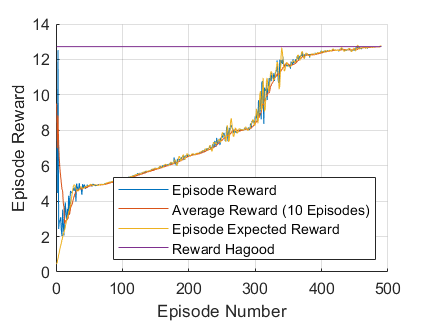

mdl="Datas\Model_EF_Tune_Shunt_R_TRPO.mat";
load(mdl,'trainingStats','stop_training_value')
    
figure
hold on
plot(trainingStats.EpisodeIndex,trainingStats.EpisodeReward)
plot(trainingStats.EpisodeIndex,trainingStats.AverageReward)
plot(trainingStats.EpisodeIndex,trainingStats.EpisodeQ0)
plot([1 trainingStats.EpisodeIndex(end)],[stop_training_value stop_training_value])
    
legend('Episode Reward','Average Reward (10 Episodes)','Episode Expected Reward','Reward Hagood','Location','southeast')
xlabel('Episode Number')
ylabel('Episode Reward')
grid("on")

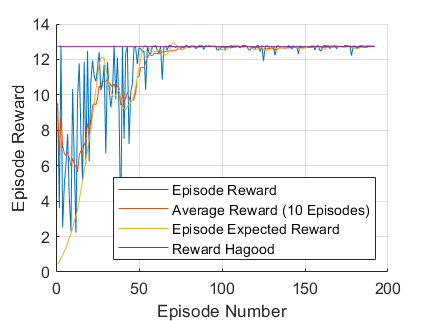


if save_figure_var == 1
    savefig('Training_TRPO_shunt_R')
    save_fig_pdf('Training_TRPO_shunt_R')
end  

mdl="Datas\Model_EF_Tune_Shunt_R_PPO.mat";
load(mdl,'trainingStats')
    
figure
hold on
plot(trainingStats.EpisodeIndex,trainingStats.EpisodeReward)
plot(trainingStats.EpisodeIndex,trainingStats.AverageReward)
plot(trainingStats.EpisodeIndex,trainingStats.EpisodeQ0)
plot([1 trainingStats.EpisodeIndex(end)],[stop_training_value stop_training_value])
    
legend('Episode Reward','Average Reward (10 Episodes)','Episode Expected Reward','Reward Hagood','Location','southeast')
xlabel('Episode Number')
ylabel('Episode Reward')
grid("on")


if save_figure_var == 1
    savefig('Training_PPO_shunt_R')
    save_fig_pdf('Training_PPO_shunt_R')
end

## Step 4 - Simulation

### *Step 4-1: Simulation options:*

mdl="Data\Model_EF_Tune_Shunt_R_TRPO.mat";
load(mdl,'agent')

Error using load
Unable to find file or directory
'Data\Model_EF_Tune_Shunt_R_TRPO.mat'.

rng(0)
obs = reset(env);
action = getAction(agent,{obs})
[nextObs,reward,isdone] = step(env,action{1});
R_opt_TRPO = 10^(action{1})


mdl="Data\Model_EF_Tune_Shunt_R_PPO.mat";
load(mdl,'agent')
rng(0)
obs = reset(env);
action = getAction(agent,{obs})
[nextObs,reward,isdone] = step(env,action{1});
R_opt_PPO = 10^(action{1})

mdl="Data\Model_EF_Tune_Shunt_RLC_Biblio.mat";
load(mdl,'R_opt_Hagood','R_opt_preumont')

Bode

R_value=[R_opt_preumont R_opt_Hagood R_opt_TRPO R_opt_PPO];
color=['r'; 'b'; 'c'; 'k'; 'g'; 'm'];

feedin = 1; %V
feedout = 1; %q

interval_plot=[2000:0.01:4000];
g=bodeoptions;
g.FreqScale='Linear';
g.PhaseWrapping ='on';
g.Grid='on';
g.XLim={[2e3 4e3]};

figure
hold on
bode(Sys_sc(end-1,2),interval_plot,g)
bode(Sys_oc(end-1,2),interval_plot,g)

for i=1:length(R_value)
Controle=s*R_value(i);
Sys_rs_contr_R = feedback(Sys_rs,Controle,feedin,feedout);
bode(Sys_rs_contr_R(end-1,2),interval_plot,color(i+2),g)
end

legend('Short circuit', ...
       'Open Circuit', ...
       'Preumont R_{opt}=10^{'+string(log10(R_opt_preumont))+'}', ...
       'Hagood R_{opt}=10^{'+string(log10(R_opt_Hagood))+'}', ...
       'TRPO R_{opt}=10^{'+string(log10(R_opt_TRPO))+'}', ...
       'PPO R_{opt}=10^{'+string(log10(R_opt_PPO))+'}', ...
       'Location','southwest')
hold off

if save_figure_var == 1
    savefig('Bode_Sys_1D_R_opt_RL')
    save_fig_pdf('Bode_Sys_1D_R_opt_RL')
end

Pole/Zero Plot

R_value=[R_opt_preumont R_opt_Hagood R_opt_TRPO R_opt_PPO];
color=['r'; 'b'; 'c'; 'k'; 'g'; 'm'];
marker=['o'; 'x'; 'p'; '+'; 's'; 'd'];

figure
hold on
poles_sc=pole(Sys_sc(end-1,2));
scatter(real(poles_sc),imag(poles_sc),marker(1),color(1))
poles_oc=pole(Sys_oc(end-1,2));
scatter(real(poles_oc),imag(poles_oc),marker(2),color(2))

for i=1:length(R_value)
Controle=s*R_value(i);
Sys_rs_contr_R = feedback(Sys_rs,Controle,feedin,feedout);
poles_rs=pole(Sys_rs_contr_R);
scatter(real(poles_rs),imag(poles_rs),marker(i+2),color(i+2))
end

xlim([-140 0.01])
ylim([2000 4000])
xlabel('Real part of poles')
ylabel('Imaginary part of poles')

grid("on")
legend('Short circuit', ...
       'Open Circuit', ...
       'Preumont R_{opt}=10^{'+string(log10(R_opt_preumont))+'}', ...
       'Hagood R_{opt}=10^{'+string(log10(R_opt_Hagood))+'}', ...
       'TRPO R_{opt}=10^{'+string(log10(R_opt_TRPO))+'}', ...
       'PPO R_{opt}=10^{'+string(log10(R_opt_PPO))+'}', ...
       'Location','southwest')

if save_figure_var == 1
    savefig('PZ_Sys_1D_R_opt_RL')
    save_fig_pdf('PZ_Sys_1D_R_opt_RL')
end

Noise response

R_value=[R_opt_preumont R_opt_Hagood R_opt_TRPO R_opt_PPO];
color=['r'; 'b'; 'c'; 'k'; 'g'; 'm'];

figure
plot(env.time,env.w10_0)

for i=1:length(R_value)
    reset(env)
    step(env,log10(R_value(i)));
    hold on
    plot(env.time(1:length(env.time)/(i)),env.w10(1:length(env.time)/(i)),color(i+2))
end
legend('Short circuit', ...
       'Preumont R_{opt} = 10^{'+string(log10(R_opt_preumont))+'}', ...
       'Hagood R_{opt} = 10^{'+string(log10(R_opt_Hagood))+'}', ...
       'TRPO R_{opt} = 10^{'+string(log10(R_opt_TRPO))+'}', ...
       'PPO R_{opt} = 10^{'+string(log10(R_opt_PPO))+'}', ...
       'Location','northwest')
xlabel('Time (s)')
ylabel('w_{10}')

if save_figure_var == 1
    savefig('Noise_Sys_1D_R_opt_RL')
    save_fig_pdf('Noise_Sys_1D_R_opt_RL')
end

Impulse response

R_value=[R_opt_preumont R_opt_Hagood R_opt_TRPO R_opt_PPO];
color=['r'; 'b'; 'c'; 'k'; 'g'; 'm'];

figure
hold on
impulse(Sys_rs(end-1,2),time(end))
for i=1:length(R_value)
    Controle=s*R_value(i);
    Sys_rs_contr_R = feedback(Sys_rs,Controle,feedin,feedout);
    impulse(Sys_rs_contr_R(end-1,2),time(end),color(i+2))
end

legend('Short circuit', ...
       'Preumont R_{opt} = 10^{'+string(log10(R_opt_preumont))+'}', ...
       'Hagood R_{opt} = 10^{'+string(log10(R_opt_Hagood))+'}', ...
       'TRPO R_{opt} = 10^{'+string(log10(R_opt_TRPO))+'}', ...
       'PPO R_{opt} = 10^{'+string(log10(R_opt_PPO))+'}', ...
       'Location','northwest')
xlabel('Time (s)')
ylabel('w_{10}')

if save_figure_var == 1
    savefig('Impulse_Sys_1D_R_opt_RL')
    save_fig_pdf('Impulse_Sys_1D_R_opt_RL')
end


Reward variation 

mdl="Data\Model_EF_Tune_Shunt_R_TRPO.mat";
load(mdl,'env')
mdl="Data\Model_EF_Tune_Shunt_RLC_Biblio.mat";
load(mdl,'R_opt_Hagood','R_opt_preumont')
color=['r'; 'b'; 'c'; 'k'; 'g'; 'm'];
marker=['o'; 'x'; 'p'; '+'; 's'; 'd'];

R_value=10.^[0:0.5:12];
warning('off','all')

for i=1:length(R_value)
    reset(env);
    [nextObs,reward(i),isdone] = step(env,log10(R_value(i)));
end

figure
semilogx(R_value,reward(1:length(R_value)))
hold on
scatter(R_opt_Hagood,stop_training_value,marker(4),color(4))
xlabel('R_{shunt}')
ylabel('Reward')
grid('on')

annotation('textbox',...
    [0.479928571428571 0.849047619047621 0.0447142857142857 0.0723809523809524],...
    'String',{'(2)'},...
    'FontSize',12,...
    'FitBoxToText','off',...
    'EdgeColor','none');

% Create textbox
annotation('textbox',...
    [0.197785714285714 0.253809523809527 0.0447142857142858 0.0723809523809527],...
    'String','(1)',...
    'FontSize',12,...
    'FitBoxToText','off',...
    'EdgeColor','none');

% Create textbox
annotation('textbox',...
    [0.75135714285714 0.313809523809529 0.0447142857142857 0.0723809523809529],...
    'String','(3)',...
    'FontSize',12,...
    'FitBoxToText','off',...
    'EdgeColor','none');


if save_figure_var == 1
    savefig('Reward_Sys_1D_R_opt_RL')
    save_fig_pdf('Reward_Sys_1D_R_opt_RL')
end

# Function Glossary

Function to create critic network.

function criticNetwork = localCreateCriticNetwork(ObsInfo,numActions,nNN)
NumHiddenUnitC=nNN;   
DltInputDimension= prod(ObsInfo.Dimension);
criticnet_default=[featureInputLayer(DltInputDimension,'Name', 'input_1'), ...
                        fullyConnectedLayer(NumHiddenUnitC, 'Name', 'fc_1','WeightsInitializer','he','BiasInitializer','zeros'), ...
                        reluLayer('Name','relu_body'),...
                        fullyConnectedLayer(NumHiddenUnitC, 'Name', 'fc_2','WeightsInitializer','he','BiasInitializer','zeros'), ...
                        reluLayer('Name','relu_body2'),...
                        fullyConnectedLayer(1, 'Name', 'output','WeightsInitializer','he','BiasInitializer','zeros')]; %fullyConnectedLayer(NumHiddenUnitC, 'Name', 'fc_2'), ...
                                                                   %reluLayer('Name','relu_body2'),...                        
                        
        
criticNetdefault=layerGraph(criticnet_default);
criticNetwork=criticNetdefault;

end 

Function to create actor network.

function actorNetwork = localCreateActorNetwork(ObsInfo,ActInfo,nNN)

NumHiddenUnitA = nNN;
DltInputDimension= prod(ObsInfo.Dimension);
numAct= prod(ActInfo.Dimension);
inputGraph=[featureInputLayer(DltInputDimension, 'Name', 'input_1'),...
                    fullyConnectedLayer(NumHiddenUnitA, 'Name', 'fc_1','WeightsInitializer','he','BiasInitializer','zeros'),...
                    reluLayer('Name','body_output1'),...
                    fullyConnectedLayer(NumHiddenUnitA, 'Name', 'fc_2','WeightsInitializer','he','BiasInitializer','zeros'),...
                    reluLayer('Name','body_output')]; %reluLayer('Name','relu_body'),...
                                                      %fullyConnectedLayer(NumHiddenUnitA, 'Name', 'fc_2'), ... 
                    
        
    meanPath = fullyConnectedLayer(numAct, 'Name', 'fc_mean','WeightsInitializer','he','BiasInitializer','zeros');
    
    [Scale, Bias] = getTanhScaleBias(ActInfo);
    Scale = Scale{:};
    Bias  = Bias{:};
    tanhScaleLayer = [
                tanhLayer('Name','tanh'),...
                scalingLayer('Name','scale','Scale',Scale,'Bias',Bias)]; %(X*Scale+bias)
        
meanPath = [
                meanPath,...
                tanhScaleLayer];
stdPath = [
            fullyConnectedLayer(numAct, 'Name', 'fc_std');
            softplusLayer('Name', 'std');
            ];
    
    
actornet_default = layerGraph(inputGraph);
actornet_default = addLayers(actornet_default, meanPath);
actornet_default = addLayers(actornet_default, stdPath);
actornet_default = connectLayers(actornet_default,'body_output','fc_mean');
actornet_default = connectLayers(actornet_default,'body_output','fc_std');
actorNetwork=actornet_default;
end 